clc;
clear all;
addpath('processed_data');
addpath('outputs');
addpath('src\functions\');
addpath('src\model\');
addpath('src\SAFE_sensitivity_analysis\sampling');
addpath('src\SAFE_sensitivity_analysis\EET');
addpath('src\SAFE_sensitivity_analysis\visualization');
addpath('src\model\');
addpath('src\visualization\');

## data loading

load('processed_data/data.mat');
N = size(data,1);
load('processed_data/temperature.mat');
 
% densities
years = data.year(1:N-1);
juveniles = data.juveniles_density(1:N-1)/2;
adult_fems = data.adult_fems_density(1:N-1);
tot_crabs = data.total_crabs_density(1:N-1);

time_ode = [1:1:(N-1)*12]';

T_ode = reshape(T(:,1:N-1),[],1);

% initial conditions
X0_state = [juveniles(1);adult_fems(1)];

% training set
years_train = data.year(1:floor(0.8*(N-1)));
juveniles_train = data.juveniles_density(1:floor(0.8*(N-1)))/2;
adult_fems_train = data.adult_fems_density(1:floor(0.8*(N-1)));
time_ode_train = [1:1:floor(0.8*(N-1))*12]';
T_ode_train = T_ode(1:floor(0.8*(N-1))*12);

% validation set
years_val = data.year(floor(0.8*(N-1))+1:N-1);
juveniles_val = data.juveniles_density(floor(0.8*(N-1))+1:N-1)/2;
adult_fems_val = data.adult_fems_density(floor(0.8*(N-1))+1:N-1);
time_ode_val = [floor(0.8*(N-1))*12+1:1:(N-1)*12]';
T_ode_val = T_ode(floor(0.8*(N-1))*12+1:(N-1)*12);

% initial conditions
X0_train = [juveniles_train(1);adult_fems_train(1)];
X0_val = [juveniles_val(1);adult_fems_val(1)];

## sensitivity analysis

performed with: Pianosi, F., Sarrazin, F., Wagener, T. (2015), A Matlab toolbox for Global Sensitivity Analysis, Environmental Modelling & Software, 70, 80-85, oi: 10.1016/j.envsoft.2015.04.009.

% threshold for selecting critical parameters
thresh = 0.03;

% either run this (takes approx half hour):
% SA_out = run_sensitivity_analysis(time_ode, T_ode, X0_state, juveniles, adult_fems, thresh);
% save('outputs\sensitivity_analysis_out.mat','SA_out');

% or load already saved ouputs:
load('outputs\sensitivity_analysis_out.mat');

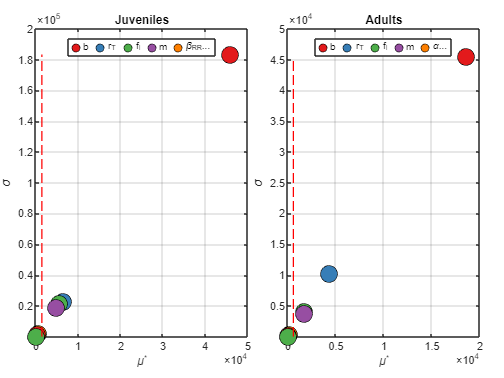

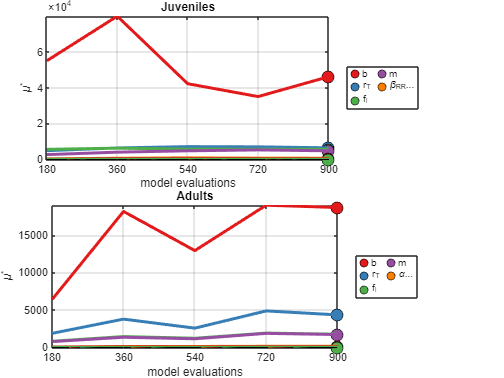

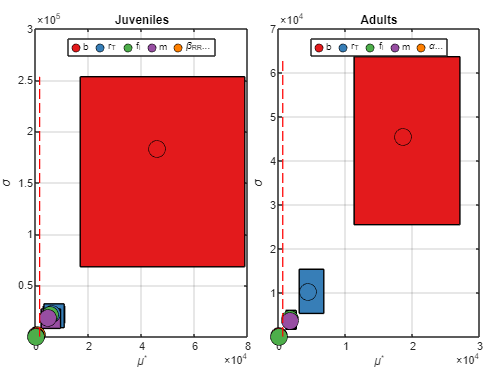

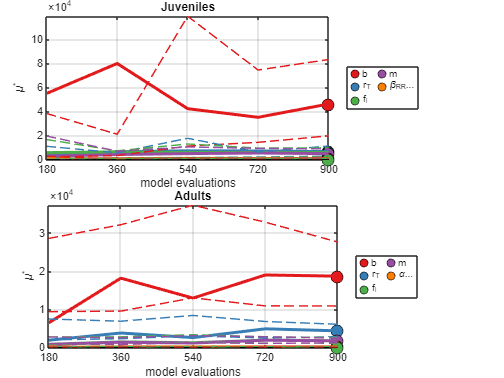

plot_sensitivity_analysis(SA_out);

## calibration

performed using gamultiobj

% parameters selection (threshold = 3%)
max_mi_J = max(SA_out.mi_J);
max_mi_A = max(SA_out.mi_A);

selected_parameters_indices = union(find(SA_out.mi_J>=0.03*max_mi_J),...
    find(SA_out.mi_A>=0.03*max_mi_A));

% either run this (takes approx 1 hour):
%cal_out = run_calibration(time_ode_train, X0_train, juveniles_train, adult_fems_train, T_ode_train, selected_parameters_indices);
%save('outputs\calibration_out.mat','cal_out');

% or load alreay saved outputs:
load('outputs\calibration_out.mat');


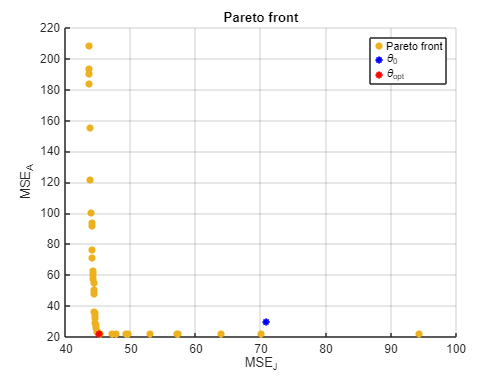

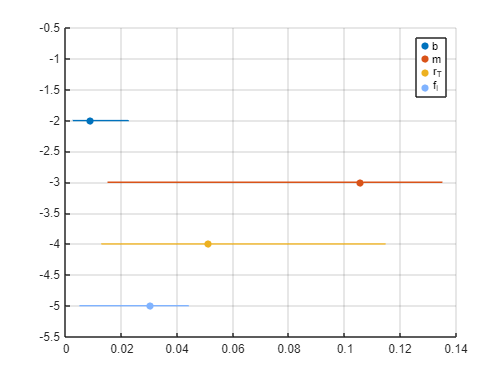

plot_calibration(cal_out)

## plots

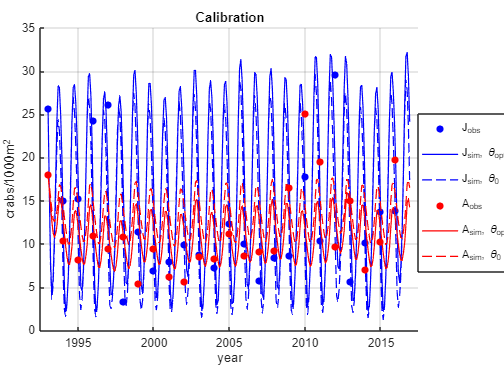

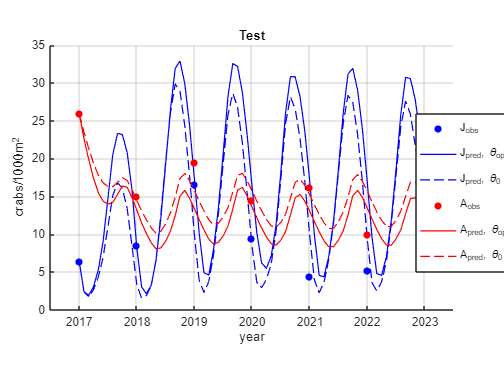

params_opt = cal_out.params_opt;
plot_results(T_ode_train, time_ode_train, years_train, X0_train, juveniles_train, adult_fems_train, T_ode_val, time_ode_val, years_val, X0_val, juveniles_val, adult_fems_val, params_opt);

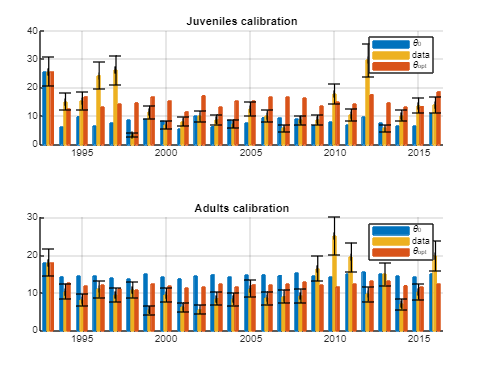

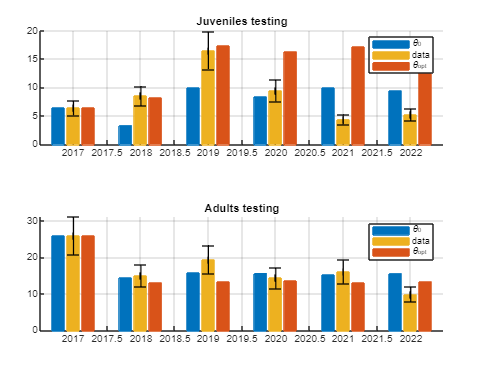

barplot_results(T_ode_train, time_ode_train, years_train, X0_train, juveniles_train, adult_fems_train, T_ode_val, time_ode_val, years_val, X0_val, juveniles_val, adult_fems_val, params_opt);